clc; clear; close all;

This supplemental code will act as a guide for the problems in the lecture. I will let you know when to run each piece of code.

## Hardy Cross Method

% ================== Network Keys ==================
% Nodes:
%   A = top-left (source node)
%   B = top-right
%   C = bottom-right
%   D = bottom-left
%
% Pipes (from -> to):
%   1: D -> A   (left vertical)
%   2: A -> C   (diagonal)
%   3: A -> B   (top horizontal)
%   4: D -> C   (bottom horizontal)
%   5: B -> C   (right vertical)
% ==================================================

%% ---------------- YOUR CODE STARTS HERE ----------------


Q_source = 8;    % Source flowrate [gpm]
q_d      = 2;    % Demand flowrate [gpm]


%% ---------------- YOUR CODE ENDS HERE ----------------


Q_surplus = Q_source - 4*q_d; 
if Q_surplus < -1e-12
    error('Source is smaller than total demand. Increase Q_source or reduce q_d.');
end


pipes = [ ...
%1 D->A
               300     6     130;
%2 A->C (diagonal)
               424     6     130;
%3 A->B
               300     4     130;
%4 D->C
               300     6     130;
%5 B->C
               300     6     130];

L = pipes(:,1); d = pipes(:,2); C = pipes(:,3);

% Hazen–Williams in English units
n     = 1.852;
coef  = 10.67/2.31;
RHW   = coef .* L ./ ( C.^n .* d.^4.871 ); 

% Loop 1
LoopU.pipes = [3 5 2];
LoopU.sign  = [+1 +1 -1];

% Loop 2
LoopL.pipes = [2 4 1];
LoopL.sign  = [+1 -1 +1];
Loops = {LoopU, LoopL};

% Initial guess 
Q = zeros(5,1);
Q(3) = +3;   
Q(2) = +3;   
Q(5) = Q(3) - 2;  
Q(4) = 2 - Q(2) - Q(5);
Q(1) = 0;  

% Hardy-Cross iterations
maxIter = 200;
tol_dQ  = 1e-5;   
lambda  = 0.6;      

for k = 1:maxIter
    dQ_max = 0;
    for Lp = 1:numel(Loops)
        idx = Loops{Lp}.pipes(:);
        sgn = Loops{Lp}.sign(:);

        Qi = Q(idx).*sgn;                      
        hi = RHW(idx).*abs(Qi).^n.*sign(Qi);           
        denom = n.*RHW(idx).*max(abs(Qi),1e-12).^(n-1); 

        dQ = -sum(hi)/sum(denom);
        dQ = lambda*dQ;

        Q(idx) = Q(idx) + dQ.*sgn;
        dQ_max = max(dQ_max, abs(dQ));
    end

    if dQ_max < tol_dQ
        break;
    end
    if k==maxIter
        fprintf('Warning: Max iterations reached. Max |dQ| = %.3e gpm\n', dQ_max);
    end
end

% Results
hf = RHW .* abs(Q).^n .* sign(Q);  % signed psi drop from "from->to"

names = ["1 D->A","2 A->C","3 A->B","4 D->C","5 B->C"]';
T = table(names,L,d,C,Q,hf,'VariableNames', ...
    {'Pipe','L_ft','d_in','C','Q_gpm','DeltaP_psi'});
disp(T);

      Pipe      L_ft    d_in     C      Q_gpm      DeltaP_psi 
    ________    ____    ____    ___    ________    ___________

    "1 D->A"    300      6      130     -2.6683    -0.00016813
    "2 A->C"    424      6      130      2.3041     0.00018108
    "3 A->B"    300      4      130      1.0277       0.000207
    "4 D->C"    300      6      130     0.66825     1.2944e-05
    "5 B->C"    300      6      130    -0.97232    -2.5924e-05



## Steady-State Chamber Pressure

% Tank Conditions
P_tank = 400; % Tank Pressure [psia]
T_tank = 110; % Tank Temp. [K]
rho_tank = 427.16; % Methane Density [kg/m^3]

% Line Conditions
CdA = 1.11; % Line CdA [cm^2]

% Chamber Conditions
MR = 3.2; % Mixture Ratio
At = 5.42; % Throat Area [in^2]
MW = 20.742; % Combustion Mol. Weight [g/mol]
R = 8314.46; % Universal Gas Constant [J/kmol-K]
Tc = 3347.12; % Chamber Temperature [K]
gamma = 1.127; % Chamber Specifc Heat Ratio
Cd_throat = 1.0; % Throat Cd

% Ambient Conditions
P_amb = 14.67; % Ambient Pressure [psia]


% Unit conversions
P_tank  = P_tank * 6894.76;     % Pa
At      = At * 0.00064516;      % m^2
R       = R / MW;               % J/(kg-K)
CdA     = CdA * 1e-4;           % m^2



%% ---------------- YOUR CODE STARTS HERE ----------------

Pc_guess = 100; % guess chamber pressure (psia)

% choked flow out of engine:
TCA_mdot  = @(Pc) Cd_throat * At .* Pc .* sqrt(gamma/(R*Tc)) .* (2/(gamma+1))^((gamma+1)/(2*(gamma-1)));

% incompressible fuel flow:
Line_mdot = @(Pc) CdA .* sqrt(2*rho_tank.*max(P_tank - Pc,0));

% residual equation to be solved for f(P) = 0:
residual  = @(Pc) Line_mdot(Pc) - TCA_mdot(Pc);

%% ---------------- YOUR CODE ENDS HERE ----------------



% Root Solver:
Pc_Pa     = fzero(residual, Pc_guess*6894.76);
Pc_solved = Pc_Pa / 6894.76;
fprintf('Solved Chamber Pressure: %.3f psia\n', Pc_solved);

Solved Chamber Pressure: 250.025 psia


## Transient Mass Flow

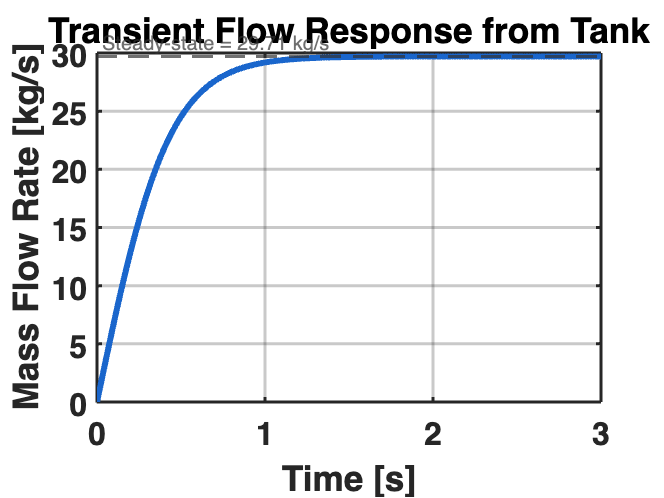

P_tank = 100;     % Tank Pressure [psig]
P_amb  = 0;       % Ambient Pressure [psig]
Cd     = 0.8;     % Line Discharge Coefficient
A      = 10;      % Line Cross-Sectional Area [cm^2]
l      = 10;      % Line Length [m]
rho    = 1000;    % Water Density [kg/m^3]
mdot_0 = 0;       % Initial Mdot [kg/s]
dt     = 0.01;    % Timestep Increment [s]
t_end  = 3;       % Simulation End Time [s]

% Unit conversions
P_tank = P_tank * 6894.76;   % Pa
P_amb  = P_amb * 6894.76;    % Pa
A  = A * 1e-4;               % m^2

% Time and Mdot vectors
t = 0:dt:t_end;
mdot = zeros(size(t));
mdot(1) = mdot_0;



%% ---------------- YOUR CODE STARTS HERE ----------------


% Resistance
R = 1 / (2 * (Cd * A)^2);

% Inertance
L = l / A;    

% Transient integration
for i = 1:length(t)-1
    mdot_current = mdot(i); % use this for mdot_current

    dmdot_dt = ((P_tank-P_amb) - (R / rho) * mdot_current^2) * (1 / L);
    mdot_new = mdot_current + dmdot_dt * dt;

    mdot(i+1) = mdot_new; % ignore this, this is just for updating the vector
end

%% ---------------- YOUR CODE ENDS HERE ----------------




% Plot
figure('Color', 'w');
plot(t, mdot, 'LineWidth', 3, 'Color', [0.1 0.4 0.8])
hold on
yline(max(mdot), '--', sprintf('Steady-state = %.2f kg/s', max(mdot)), ...
       'LineWidth', 1.5, 'Color', [0.2 0.2 0.2], 'LabelHorizontalAlignment','left')
xlabel('Time [s]', 'FontSize', 18, 'FontWeight', 'bold')
ylabel('Mass Flow Rate [kg/s]', 'FontSize', 18, 'FontWeight', 'bold')
title('Transient Flow Response from Tank', 'FontSize', 20, 'FontWeight', 'bold')
grid on
set(gca, ...
    'FontSize', 16, ...
    'FontWeight', 'bold', ...
    'LineWidth', 1.5, ...
    'Box', 'on', ...
    'GridAlpha', 0.25, ...
    'MinorGridLineStyle', ':', ...
    'YGrid', 'on', ...
    'XGrid', 'on', ...
    'Color', 'none');
xlim([0 max(t)])